Pierre BAGNARA

Doctorant au Centre de Recherche de l'Ecole de l'Air

pierre.bagnara@ecole-air.fr 

09/04/2025

# Formulaire récapitulatif, les bases de Matlab

## Avant d'exécuter un fichier

Sur Matlab, la notion de répertoire de travail est essentielle pour repérer les fichiers, que ce soit pour exécuter du code ou pour extraire/sauvegarder des données.

Ce répertoire de travail est le dossier dans lequel Matlab "regarde". Il est affiché entre la barre d'outils et la fenêtre d'édition (encadré en rouge dans l'image ci-dessous).

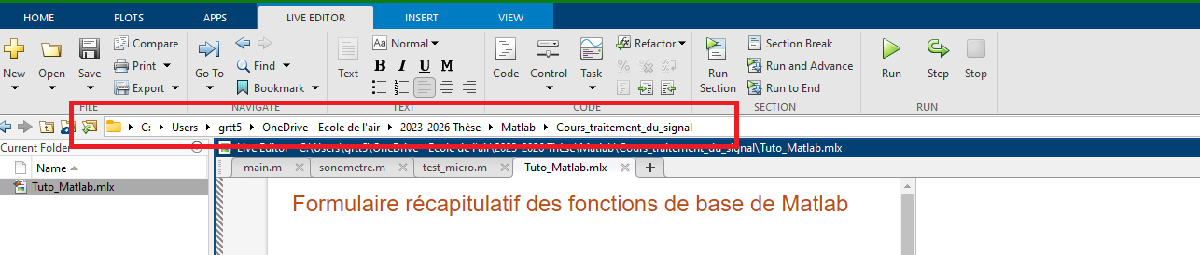

Par convention, on fait correspondre le répertoire de travail avec le lieu de stockage du fichier que l'on souhaite exécuter.

Les variables sont accessibles dans une fenêtre dédiée. On peut voir leur valeur directement si c'est possible, ou alors les afficher dans un explorateur en double-cliquant dessus.

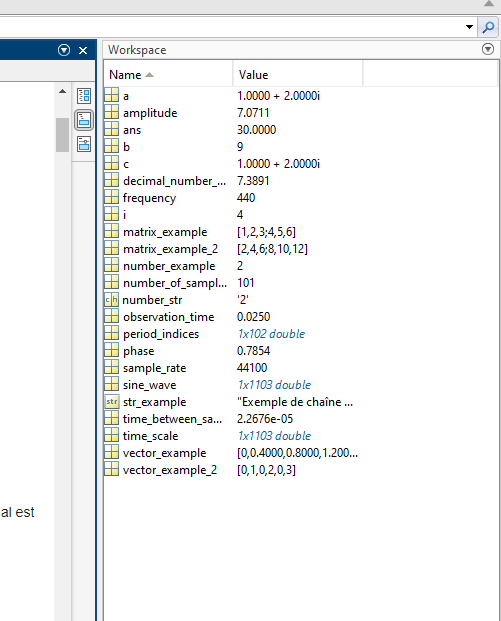

Un indicateur du statut de Matlab se situe dans le coin en bas à gacuhe, voir l'image ci-dessous.

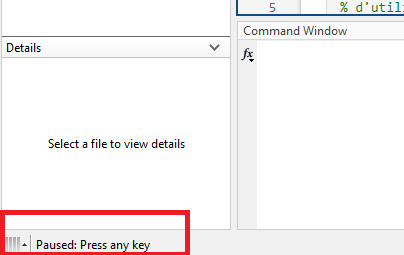

Cet indicateur peut afficher l'une des possibilités suivantes :

- Rien, ce qui signifie que Matlab n'exécute rien, il est en attente

- "Busy", ce qui signifie qu'un programme est en cours d'exécution

- "Paused: Press any key", ce qui indique que Matlab est arrêté au niveau d'une pause dans le programme, et qu'il attend un signal de l'utilisateur pour continuer. Ce signal est l'appui sur n'importe quelle touche du clavier dans la fenêtre de commande.

## Début d'un script Matlab

Un fichier exécutable commence par de la documentation.

On rédige un petit bloc de commentaires ("%" en début de ligne), qui donne le titre, quelques infos sur le script, l'auteur et la date.

% Tuto_Matlab.mlx
%
% Fichier LiveScript qui regroupe les principales fonctions Matlab
% utilisées pour le cours de traitement du signal et quelques exemples
% d'utilisation.
%
% Auteur: Pierre BAGNARA, pierre.bagnara@ecole-air.fr
% Date: 09/04/2025

Par défaut, Matlab n'efface pas les résultats des exécutions précédentes. Donc on s'assure de "faire le ménage" pour éviter de garder des valeurs obsolètes dans les variables, ou d'anciens graphiques ouverts.

clear variables  % Efface toutes les variables
close all  % Ferme toutes les figures
clc  % Efface les sorties affichées dans la fenêtre de commande

Lorsque Matlab exécute du code, il affiche par défaut tous les résultats des opérations qu'il fait dans la fenêtre de commande. Pour des scripts longs qui font beaucoup d'opérations, la fenêtre de commande peut vite se retrouver saturée par ces affichages.

Ainsi, une bonne pratique est de toujours finir ses lignes de code par un point-virgule (sauf cas exceptionnels), ce qui donne l'instruction à Matlab de ne pas afficher le résultat.

Matlab contient un certain nombre d'outils, par exemple "disp" qui permet de suivre l'évolution d'une variable au fur-et-à-mesure de l'exécution du programme.

disp('Affiche des éléments dans la fenêtre de commande')

Affiche des éléments dans la fenêtre de commande


Une aide est intégrée avec le mot-clé "help"

help disp

 disp - Display value of variable
    This MATLAB function displays the value of variable X without printing
    the variable name.

    Syntax
      disp(X)

    Input Arguments
      X - Input array
        array

    Examples
      Display Variable Values
      Display Matrix with Column Labels
      Display Multiple Variables on Same Line

    See also format, int2str, num2str, sprintf, 

Il est possible de mettre en pause l'exécution d'un programme à une ligne donnée avec la fonction "pause".

pause(1)  % Pause d'une seconde, puis reprise de l'exécution du programme.
% Ecrire "pause", ou "pause()" provoque l'attente que l'utilisateur
% appuie sur une touche pour reprendre l'exécution.

Comme dans n'importe quel autre langage de programmation, les données peuvent être de différents types: 

- Des valeurs numériques, entières ou décimales, réelles ou complexes

- Des nombres booléens

- Des matrices

- Des chaïnes de caractères

- D'autres types plus exotiques comme des objets, des tableaux de cellules, etc...

Par la suite, on passe en revue quelques aspects sur ces types de données.

## Valeurs numériques

L'utilisation des valeurs numériques est assez directe. Contrairement aux codes compilés, il n'y a pas besoin de spécifier le type d'un nombre (int, simple, double, etc...) : Matlab gère ça de façon implicite en considérant que, par défaut, tous les nombres sont des flottants double précision.

number_example = 2 ;
disp(class(number_example))

double


Pour les nombres complexes, le nombre imaginaire pur peut être appellé par "i" ou "j", qui sont des noms pré-configurés sur Matlab. Cependant, "i" et "j" sont des noms assez courants pour des variables, en particulier comme index dans une boucle for. Pour éviter une réécriture accidentelle qui peut engendrer des erreurs, on préfère appeler le nombre imaginaire pur par "1i" ou "1j" par convention.

a = 1 + 2*i ;
for i = 1:4
    continue
end
b = 1 + 2*i ;
c = 1 + 2*1i ;
disp(strcat('a= ', num2str(a))) ; disp(strcat('b= ', num2str(b))) ; disp(strcat('c= ', num2str(c)))

a=1+2i
b=9
c=1+2i


## Nombres booléens

Les deux nombres booléens peuvent être appelés par "true" et "false", ou alors "1" et "0". Les opérations logiques principales sont données par la suite.

true && false  % Opération ET logique

ans = logical
   0


1 || 0  % Opération OU logique

ans = logical
   1


~true  % Opération NON logique

ans = logical
   0


## Chaînes de caractères

Les chaines de caractères sont définies soit entre guillemets.

str_example = "Exemple de chaîne de caractères"

str_example = "Exemple de chaîne de caractères"

Les opérations les plus utiles des chaînes de caractères sont les suivantes :

str_example.split()  % Sépare les mots de la chaîne de caractères

ans = 5×1 string array
    "Exemple"
    "de"
    "chaîne"
    "de"
    "caractères"


number_str = num2str(number_example)  % Convertit un nombre en une chaîne de caractères

number_str = '2'

str2double(number_str)  % Convertit une chaîne de caractères en nombre

ans = 2

strcat(str_example, number_str)  % Fusionne des chaînes de caractères

ans = "Exemple de chaîne de caractères2"

strcmp(str_example, 'autre exemple')  % Compare deux chaînes de caractères et indique si elles sont identiques ou pas

ans = logical
   0


## Matrices

Les matrices sont définies entre crochets. Les éléments en ligne sont séparés par des virgules, et les éléments en colonne sont séparés par des point-virgules.

matrix_example = [1, 2, 3 ; 4, 5, 6]

matrix_example =      1     2     3
     4     5     6


La taille d'une matrice est retournée par les fonctions "size" et "length"

size(matrix_example)  % Taille de la matrice selon chaque dimension

ans =      2     3


length(matrix_example)  % Taille de la matrice selon sa dimension la plus grande

ans = 3

La transposée Hermitienne d'une matrice est obtenue par une apostrophe. La fonction transpose() renvoie la transposée standard (non-conjuguée)

matrix_example'

ans =      1     4
     2     5
     3     6


Un élément d'une matrice peut être ciblé avec ses indices selon les différentes dimensions. Dans notre example, pour accéder à l'élément situé à la première ligne et la troisième colonne:

matrix_example(1, 3)

ans = 3

**Note:** Contrairement à la majorité des langages de programmation, sur Matlab la numérotation des indices commence à 1

Un fragment de matrice peut être obtenu avec la syntaxe suivante:

matrix_example(1:2, 2:3)  % Sélectionne uniquement les lignes de 1 à 2 et les colonnes de 2 à 3

ans =      2     3
     5     6


Pour accéder à une ligne ou à une colonne toute entière, on utilise la notation ":"

matrix_example(:, 2)  % Sélectionne les éléments de toutes les lignes et de la colonne 2

ans =      2
     5


Le dernier élément selon une dimension est référencé par le mot "end"

matrix_example(end, end-1)  % Sélectionne l'élément de la dernière ligne et l'avant-dernière colonne

ans = 5

**Note:** Sur Matlab, les vecteurs et les scalaires sont traités de la même mainière que les matrices:

number_example(1, end)

ans = 2

Ainsi, il est important de veiller aux dimensions des variables lorsqu'on effectue des opérations mathématiques, la multiplication est, par défaut, un produit matriciel.

Dans les cas suivants, aucun problème à signaler

- multiplication de scalaires

- multiplication d'un scalaire et d'une matrice

- produit matriciel entre deux matrices si elles ont les bonnes dimensions

matrix_example_2 = number_example * matrix_example

matrix_example_2 =      2     4     6
     8    10    12


matrix_example * transpose(matrix_example_2)

ans =     28    64
    64   154


En revanche, pour des vecteurs (assimilés à des matrices sur Matlab), le produit matriciel ne fait pas de sens. On travaille plutôt avec le produit scalaire ou le produit terme-à-terme.

vector_example = [0, 0.4, 0.8, 1.2, 1.6, 2] ;
vector_example_2 = [0, 1, 0, 2, 0, 3] ;
vector_example * transpose(vector_example_2) % Produit scalaire (produit matriciel entre un vecteur ligne et un vecteur colonne)

ans = 8.8000

vector_example .* vector_example_2  % Produit terme à terme

ans =          0    0.4000         0    2.4000         0    6.0000


Même raisonnement et même manière de faire pour les divisions, les puissances, etc...

Il existe énormément de matrices "remarquables" qui ont leur propre générateur dans Matlab. Par exemple: 

zeros(2, 3)  % Matrice composée de zéros

ans =      0     0     0
     0     0     0


ones(3, 2)  % Matrice composée d'unités

ans =      1     1
     1     1
     1     1


eye(3, 3)  % Matrice identité

ans =      1     0     0
     0     1     0
     0     0     1


rand(2, 2)  % Matrice aléatoire

ans =     0.9597    0.5853
    0.3404    0.2238


Les vecteurs "remarquables" ont aussi leurs propres générateurs:

1:6  % Vecteur ligne de tous les nombres entre 1 et 6 par incrément de 1

ans =      1     2     3     4     5     6


1:2:6  % Vecteur ligne de tous les nombres entre 1 et 6 par incrément de 2

ans =      1     3     5


linspace(1, 6, 3)  % Vecteur ligne de l'intervalle [1;6] découpé en 3 points équidistants

ans =     1.0000    3.5000    6.0000


**Note:** On remarque une différence entre les résultats donnés par la notation ":" et la fonction linspace, pourtant ils partagent le même intervalle qu'ils découpent chacun en 3 points. Avec la notation ":", on impose un espacement entre les valeurs, et on adapte le nombre de points pour couvrir l'intervalle. Avec linspace, on impose le nombre de points et on adapte leur espacement pour couvrir l'intervalle. Un cas typique de génération d'un vecteur en traitement du signal est la création de l'échelle des temps, qui commence généralement à 0 et qui s'incrémente de la période d'échantillonnage à chaque nouveau pas de temps. Dans ce cas on préfère systématiquement utiliser la notation ":" pour garantir que l'incrément des valeurs temporelles correspond bien à la période d'échantillonnage utilisée.

## Fonctions mathématiques

Parmi les fonctions utiles quand on manipule des nombres, on trouve :

decimal_number_example = exp(number_example)  % Fonction exponentielle

decimal_number_example = 7.3891

log(decimal_number_example)  % Logarithme Népérien

ans = 2

log10(decimal_number_example)  % Log en base 10

ans = 0.8686

sqrt(decimal_number_example)  % Racine carrée

ans = 2.7183

round(decimal_number_example)  % Arrondi à l'entier le plus proche

ans = 7

ceil(decimal_number_example)  % Arrondi à l'entier supérieur

ans = 8

floor(decimal_number_example)  % Arrondi à l'entier inférieur

ans = 7

mean(matrix_example)  % Moyenne de chaque colonne

ans =     2.5000    3.5000    4.5000


abs([-decimal_number_example, a])  % Valeur absolue pour un nombre réel, module pour un nombre complexe

ans =     7.3891    2.2361


angle(a)  % Argument d'un nombre complexe (rad)

ans = 1.1071

Les fonctions trigonométriques et leurs réciproques sont implémentées de manière assez directe (en radians)

[sin(pi), cos(3*pi/4), tan(-pi/6), acos(0.5)]

ans =     0.0000   -0.7071   -0.5774    1.0472


deg2rad(60)  % Convertit des degrés en radians

ans = 1.0472

rad2deg(pi/6)  % Convertit des radians en degrés

ans = 30.0000

## Représentation d'un signal temporel

A titre d'illustration, on crée un signal sinusoïdal temporel que l'on affiche sur un graphique.

### Paramètres

sample_rate = 44100 ;  % Fréquence d'échantillonnage (Hz)
amplitude = 5 * sqrt(2) ;  % Amplitude de la sinusoïde (sans unité)
frequency = 440 ;  % Fréquence de la sinusoïde (Hz)
phase = pi/4 ;  % Phase de la sinusoïde (rad)
observation_time = 25 * 10^-3 ;  % Temps d'observation du signal (s)

### Création du signal

time_between_samples = 1/sample_rate ;
time_scale = 0 : time_between_samples : observation_time ;
sine_wave = amplitude * sin(2*pi*frequency*time_scale + phase) ;

%% Repérage d'une période en particulier, à afficher dans un autre graphique
number_of_samples_in_period = ceil(sample_rate / frequency) ;
period_indices = 290 : 290+number_of_samples_in_period ;  % Vecteur des indices qui forment une période du signal 
% 290 a été choisi arbitrairement, il s'agit de l'indice de départ de la
% période à afficher

### Affichage

figure(1)  % Ouvre et sélectionne la fenêtre d'affichage n°1

%% Premier graphique
subplot(2, 1, 1)  % Découpe la fenêtre selon 2 lignes et 1 colonne, soit 2 zones d'affichage, puis sélectionne la 1ère zone.
plot(time_scale, sine_wave)  % Trace une courbe sous forme de ligne continue
title("Exemple de signal temporel")
xlabel("Temps (s)")

%% Deuxième graphique
subplot(2, 1, 2)  % Sélectionne la deuxième zone d'affichage
stem(time_scale(period_indices), sine_wave(period_indices))  % Trace une courbe sous forme de points reliés à l'axe des abscisses
title("Zoom sur une période")
grid on  % Affiche le quadrillage
xlabel("Temps (s)")

Pour mettre en évidence la période qui est affichée sur le graphique zoomé, on retrace cette période sur le premier graphique dans une autre couleur, en la superposant avec la courbe déjà existante.

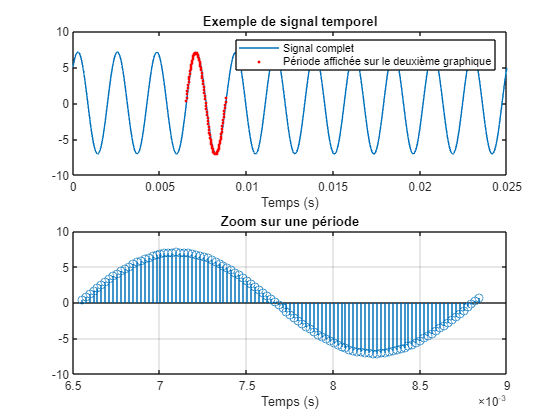

subplot(2, 1, 1)  % Re-sélectionne la première zone d'affichage
hold on  % Indique que l'on veut ajouter une courbe sans effacer ce qui est déjà affiché
scatter(time_scale(period_indices), sine_wave(period_indices), '.r')  % Trace une courbe en pointillés (scatter) petits et rouges ('.r')
legend('Signal complet', 'Période affichée sur le deuxième graphique')  % Affiche la légende des courbes

## Structures de programme

On retrouve sur Matlab les strucutres usuelles: boucles "for" et "while", test "if", etc... L'indentation n'est pas prise en compte, c'est le mot-clé "end" qui met fin à une structure.

for i = 1:3  % i est l'index de la boucle, on précise l'ensemble des valeurs successives de i par un vecteur
    disp(strcat('i=', num2str(i)))
end

i=1
i=2
i=3


i = 1 ;
while i <= 3  % i <= 3 est la condition de validité de la boucle. Lorsqu'elle n'est plus vraie, le programme sort de la boucle.
    disp(strcat('i=', num2str(i)))
    i = i + 1 ;
end

i=1
i=2
i=3


if rem(i, 2) == 0  % Condition, ici on vérifie si le reste de la division euclidienne de i par 2 vaut zéro
    % Code exécuté si la condition est vraie
    disp(strcat('i=', num2str(i), ' est un nombre pair'))
else
    % Code exécuté si la condition est fausse
    disp(strcat('i=', num2str(i), ' est un nombre impair'))
end

i=4 est un nombre pair
